# Fitting the uniform shear with incomplete information

This example calls the function fitMann to estimate the three parameters of the uniform shear model when there is "missing information". For example, one may not know everything about the three velocity components. Thus, the fitting algorithm attempt to reconstruct the spatial structure of turbulence knowing only a fraction of it. 

**Table of Contents**

[Definition of the target parameters and model ](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F142b1dc5-717a-4c0f-af58-77235a20a1ed%2Fca4bc4b4-1b17-4bec-a0ab-9b3064030363%2Ffiles%2FExample_fitting.mlx&embed=web#H_92175889)[Case 1: The stability parameter is unknown ](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F142b1dc5-717a-4c0f-af58-77235a20a1ed%2Fca4bc4b4-1b17-4bec-a0ab-9b3064030363%2Ffiles%2FExample_fitting.mlx&embed=web#H_717C616E)[Case 2: Only the along-wind velocity component is known ](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F142b1dc5-717a-4c0f-af58-77235a20a1ed%2Fca4bc4b4-1b17-4bec-a0ab-9b3064030363%2Ffiles%2FExample_fitting.mlx&embed=web#H_D56FB236)[Case 3: Only the along-wind and across-wind velocity components are known ](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F142b1dc5-717a-4c0f-af58-77235a20a1ed%2Fca4bc4b4-1b17-4bec-a0ab-9b3064030363%2Ffiles%2FExample_fitting.mlx&embed=web#H_C95049C6)[Case 4: Only the vertical velocity component is known](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2F142b1dc5-717a-4c0f-af58-77235a20a1ed%2Fca4bc4b4-1b17-4bec-a0ab-9b3064030363%2Ffiles%2FExample_fitting.mlx&embed=web#H_02F3F5C3)

## Definition of the target parameters and model

clearvars;close all;clc;
GAMMA = 3.2; % Shear parameter
L = 24; % m turbulence length scale
alphaEps =0.10; % m^(4/3)/s^2
tic
N1 = 100;
[PHI,k2,k3,k11,k2_log,k3_log] = MannTurb(alphaEps,GAMMA,L,'N1',N1);
FM0= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));
Su_target= FM0(end-N1+1:end,1,1)';
Sv_target= FM0(end-N1+1:end,2,2)';
Sw_target= FM0(end-N1+1:end,3,3)';
Suw_target= FM0(end-N1+1:end,1,3)';
k11_target = k11;
toc

Elapsed time is 1.581115 seconds.


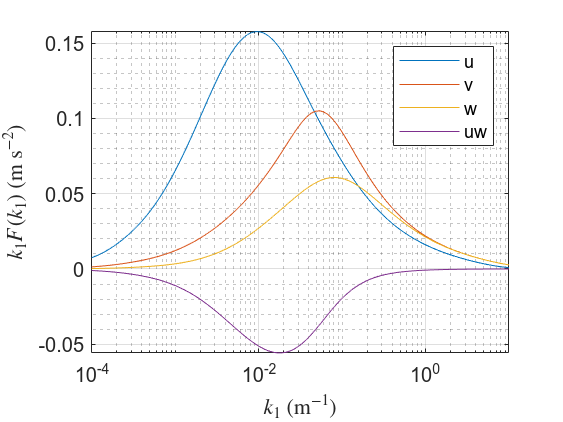


% Plot the target spectra and cross-spectra
clf;close all;
figure
semilogx(k11,k11.*Su_target);
set(gca,'yscale','lin')
hold on
semilogx(k11,k11.*Sv_target);
semilogx(k11,k11.*Sw_target);
semilogx(k11,k11.*Suw_target);
xlabel('$k_1$ (m$^{-1}$)','interpreter','latex')
ylabel('$k_1 F(k_1) $ (m s$^{-2}$)','interpreter','latex')
axis tight
set(gcf,'color','w')
axis tight
grid on
grid minor
legend('u','v','w','uw')

## Case 1: Only the along-wind velocity component is known

In this more extreme case, fitMann attempts to identify the three parameters by knowing only the longitudinal wind velocity component . The results show that the fitting procedure is providing a reasonable estimate of the length scale parameter L. That means that this approach may be used as a "poor-man" solution to study the coherence of turbulence for the u-component.  The parameter is not identified with confidence, as expected. So one should be careful when discussing the one-point velocity spectrum in this case.

Sv = []; % unknown
Sw = []; % unknown
Suw = []; % unknown
Su = Su_target;
tic
[GAMMA1,L1,alphaEps1] = fitMann(k11,Su,Sv,Sw,Suw,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          8.8138                          11.3
     1          8          1.5779        1.37311           2.13      
     2         12        0.256307        1.13168          0.473      
     3         16       0.0395599       0.741508          0.105      
     4         20      0.00717117       0.389456         0.0165      
     5         24     0.000756591       0.260514         0.0781      
     6         28     7.87395e-05       0.211962         0.0182      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

toc

Elapsed time is 13.280729 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA1, L1, alphaEps1])

Gamma = 2.8 
 L = 29.6 m
 alphaEps = 0.100 m^(4/3) s^(-2) 


## Case 2: Only the along-wind and across-wind velocity components are known

This case is similar as case 1, but we assume that the two horizontal wind velocity components are known.

Sw = []; % unknown
Suw = []; % unknown
Su = Su_target;
Sv = Sv_target;
tic
tic
[GAMMA1,L1,alphaEps1] = fitMann(k11,Su,Sv,Sw,Suw,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         12.4076                          14.1
     1          8         2.29653        1.50853           3.07      
     2         12         0.38223        1.24779          0.686      
     3         16       0.0586466       0.870305          0.151      
     4         20      0.00970238        0.62324         0.0233      
     5         24      0.00097075       0.419742         0.0747      
     6         28     5.32218e-05       0.171473         0.0273      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

toc

Elapsed time is 13.325309 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA1, L1, alphaEps1]) 

Gamma = 3.1 
 L = 24.4 m
 alphaEps = 0.098 m^(4/3) s^(-2) 


## Case 3: Only the vertical velocity component is known

This case is similar as case 2, but only the vertical velocity component is known.

Sw = Sw_target; 
Suw = []; % unknown
Su = []; % unknown
Sv = []; % unknown

tic
[GAMMA1,L1,alphaEps1] = fitMann(k11,Su,Sv,Sw,Suw,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         1.52933                          1.72
     1          8        0.286492        1.92229          0.372      
     2         12       0.0455261        1.56521         0.0803      
     3         16      0.00525406        1.06463         0.0167      
     4         20     0.000567847       0.374197        0.00293      
     5         24     0.000156451       0.518256        0.00145      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

toc

Elapsed time is 11.231117 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA1, L1, alphaEps1])

Gamma = 4.8 
 L = 23.4 m
 alphaEps = 0.118 m^(4/3) s^(-2) 


## Case 4: The co-spectrum is unknown

Only the cross-spectrum is unknown.

Sw = Sw_target; 
Suw = []; % unknown
Su = Su_target; % unknown
Sv = Sv_target; % unknown

tic
[GAMMA1,L1,alphaEps1] = fitMann(k11,Su,Sv,Sw,Suw,'N2',50,'N3',50,'N1',30);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          13.937                          15.9
     1          8         2.64184        1.65078            3.5      
     2         12        0.445365        1.37714          0.783      
     3         16        0.065749        1.00051          0.169      
     4         20      0.00836729       0.702495         0.0255      
     5         24     0.000609681       0.294974         0.0552      
     6         28      4.4451e-05       0.163709         0.0198      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<

toc

Elapsed time is 13.182233 seconds.


fprintf('Gamma = %2.1f \n L = %2.1f m\n alphaEps = %2.3f m^(4/3) s^(-2) \n',[GAMMA1, L1, alphaEps1])

Gamma = 3.2 
 L = 24.1 m
 alphaEps = 0.098 m^(4/3) s^(-2) 
